## **Problem 1**

Both parts require a set of *h *values and the function $f\left(x\right)$.

format long e

L = 12; %change L to make graph below run for smaller numbers like L=18
h = zeros(1, L);
for i = 1:L
    h(i) = 10.^(-i);
end
f = @(x) sin(x) - cos(x);
df = @(x) cos(x) + sin(x);

### ***a)***

%two point fwd
tp = @(x0, h) (f(x0 + h) - f(x0)) ./ h;
abs_errors_tp = arrayfun(@(h) abs(tp(0, h) - df(0)), h);


***b)***

%Three-Point Midpoint
tpm = @(x0, h) (1./ (2*h)) * ( f(x0 + h) - f(x0 - h) );
abs_errors_tpm = arrayfun(@(h) abs(tpm(0, h) - df(0)), h);

***Logarithmic plot***

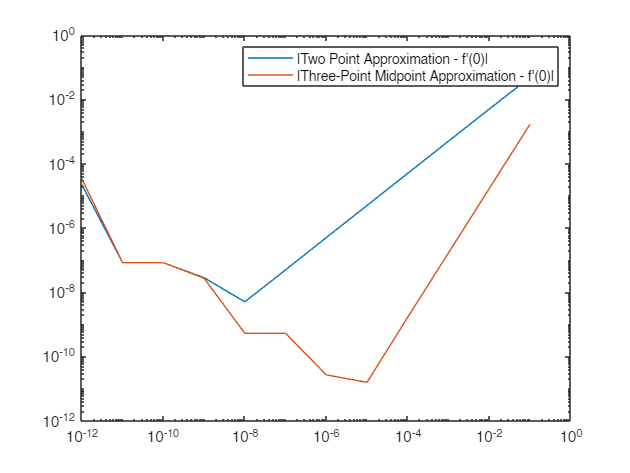

loglog(h,abs_errors_tp, h, abs_errors_tpm);
legend("|Two Point Approximation - f'(0)|", "|Three-Point Midpoint Approximation - f'(0)|");

**Error Term Domination**

For the two point formula the error term starts to take over at $h\approx {10}^{-8}$ while for the three point it occurs at $h\approx {10}^{-5}$ .